# Lab 10 – Encoding and Decoding Touch-Tone (DTMF) Signals*

# (Open-Ended Lab) 

# EE252L/CE251L: Signals and Systems Lab

## Dr. Basit Memon and Ms. Hira Mustafa

### Name: M. Shees Abbas                                                                    ID: ma11212

## Task 1

ftable = [1;2;3;4;5]*[80,110];
fs = 8000; xx = [ ];
keys = rem(3:12,10) + 1;
for ii = 1:length(keys)
kk = keys(ii);
xx = [xx,zeros(1,400)];
krow = ceil(kk/2);
kcol = rem(kk-1,2) + 1;
dur=0.15;
t=0:1/fs:dur;
xx = [xx, cos(2*pi*ftable(krow,kcol)*t)];
end
soundsc(xx,fs);

## (1)

first it make a 5x2 table for all the freq then it makes keys array from 1 to 10 then it make a empty array xx and runs a loop over the array of keys and for each itereation concatinates a delay area of 400 zeros and then an array of cos siganl of 1x1201 index and of freq defined by the elements of key array correspnding with freq table is concatinated at the end of it and the loop repeats

## (2)

the size of the table is 5x2 and of its enteries are 80, 110, 160, 220, 240, 330, 320, 440, 400, 550

and the playing order of it is as follow, 4,5,6,7,8,9,10,1,2,3

which goes as 220, 240, 330, 320, 440, 400, 550, 80, 110, 160

## (3)

the final size of the signal is 1x16010 and size of it each entry is 1x400+1x1201= 1x1601 

the total sec sound played for would be 106010/8000 = 2 sec aprox 

## Task 2

## DTMF Dail funct

function xx = dtmfdial(keyNames,fs)
%DTMFDIAL Create a signal vector of tones which will dial
% a DTMF (Touch Tone) telephone system.
%
% usage: xx = dtmfdial(keyNames,fs)
% keyNames = vector of characters containing valid key names
% fs = sampling frequency
% xx = signal vector that is the concatenation of DTMF tones.
dtmf.keys = ...
['1','2','3','A';
'4','5','6','B';
'7','8','9','C';
'*','0','#','D'];
dtmf.colTones = ones(4,1)*[1209,1336,1477,1633];
dtmf.rowTones = [697;770;852;941]*ones(1,4);
%This is an incomplete function
toneDur = 0.20; 
silDur = 0.05;
tTone = 0:1/fs:toneDur-1/fs;
silence = zeros(1, round(silDur*fs));
xx = [];
for k = 1:length(keyNames)
 [ii,jj] = find(keyNames(k) == dtmf.keys);
 f1 = dtmf.rowTones(ii,jj);
 f2 = dtmf.colTones(ii,jj);
 tone = cos(2*pi*f1*tTone) + cos(2*pi*f2*tTone);
 xx = [xx, silence, tone];
end
end



## Task 3

function beta = maxbeta(L, fb, fs)
n = 0:L-1;
h = cos(2*pi*fb*n/fs);
[H, w] = freqz(h, 1, 1024);
peak = max(abs(H));
beta = 1/peak;
end

L = 51;
fb = 852;
fs = 8000;
beta = maxbeta(L, fb, fs);
disp('Beta value:');

Beta value:


disp(beta);

    0.0394



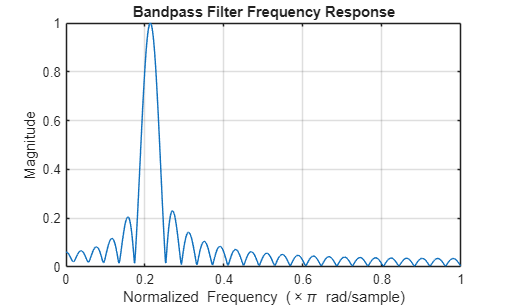


n = 0:L-1;
h = beta * cos(2*pi*fb*n/fs);

[H,w] = freqz(h,1,1024);
figure;
plot(w/pi, abs(H));
title('Bandpass Filter Frequency Response');
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude');
grid on;

## Task 4

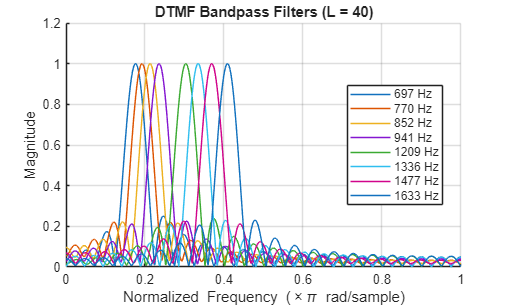

function hh = dtmfdesign(fcent, L, fs)
N = length(fcent);
hh = zeros(L, N);
for k = 1:N
 n = 0:L-1;
 h = cos(2*pi*fcent(k)*n/fs);
 beta = maxbeta(L, fcent(k), fs);
 h = beta * h;
 hh(:,k) = h;
end
end


fs = 8000;
L = 40;
fcent = [697 770 852 941 1209 1336 1477 1633];
hh = dtmfdesign(fcent, L, fs);
w = linspace(0, pi, 1024);
figure;
hold on;
legendNames = strings(1,8);


for k = 1:8
 H = freqz(hh(:,k), 1, w);
 plot(w/pi, abs(H));
 legendNames(k) = string(fcent(k)) + " Hz";
 end
title('DTMF Bandpass Filters (L = 40)');
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude');
grid on;
legend(legendNames, 'Location', 'best');

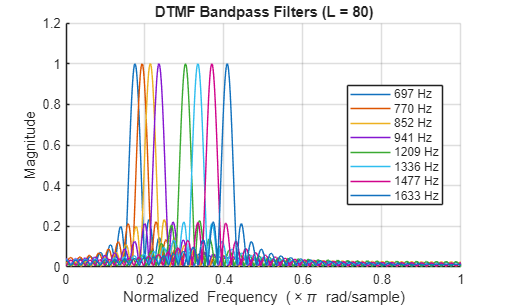




L = 80;
hh = dtmfdesign(fcent, L, fs);
figure;
hold on;
legendNames = strings(1,8);
for k = 1:8
 H = freqz(hh(:,k), 1, w);
 plot(w/pi, abs(H));
 legendNames(k) = string(fcent(k)) + " Hz";
end
title('DTMF Bandpass Filters (L = 80)');
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude');
grid on;
legend(legendNames, 'Location', 'best');

# 4. EFFECTS OF FILTERING LENGTH L ON PASSBAND WIDTH:

The passband width of an FIR bandpass filter is inversely related to the filter length L. This means that when the filter length increases, the main lobe of the frequency response becomes less or narrow. 

In the comparison between L=40 and L=80, this behavior is clearly observed. For L=40, the frequency responses are relatively wider, meaning each filter allows a broader range of frequencies to pass. As a result, there is more overlap between adjacent DTMF frequency bands. This can cause interference between neighboring tones. 

When L=80, the filters become much sharper and more selective. The main lobes become narrower, and the transition between passband and stopband becomes more abrupt. This reduces overlap between adjacent frequencies and improves frequency discrimination.

Therefore, the statement is true: increasing LLL reduces passband width and improves selectivity.

# 5. Selectivity of the bandpass filters

The bandpass filters in the DTMF system are designed to isolate specific sinusoidal components corresponding to the standard DTMF frequencies. Each filter ideally passes only one frequency while attenuating all others. 

From the frequency response plots, it can be seen that each filter has a peak at its center frequency and much lower response at other frequencies. However, since the filters are not perfectly ideal, some overlap still exists between nearby frequency bands, especially when L is small (such as L=40).

For larger L, the filters become more selective, meaning they better isolate a single frequency component and decrease others. In this case, most filters are narrow enough to separate the DTMF tones effectively. 

However, the separation is not equally easy for all frequencies. The closest spaced frequencies in the DTMF set are more difficult to isolate.

The most challenging filter design occurs in row tones. These frequencies are relatively close compared to others, so their frequency responses tend to overlap more. This makes it harder for a single filter length L to fully separate them without interference. For example: 852 Hz and 941 Hz

## DTMF cut

% %==========================================
% 
% function dtmfsig = dtmfdial(nums,fs)
% %DTMFDIAL  Create a vector of tones which will dial 
% %           a DTMF (Touch Tone) telephone system.
% %
% % usage:  dtmfsig = dtmfdial(nums) 
% %      nums = vector of numbers ranging from 1 to 12
% %        fs = sampling frequency
% %   dtmfsig = vector containing the corresponding tones.
% %
% 
% tone_cols = ones(4,1)*[1209,1336,1477];
% tone_rows = [697;770;852;941]*ones(1,3);
% 
% %==========================================
% 
%  function keys = dtmfrun(xx,L,fs)
%  %DTMFRUN    keys = dtmfrun(xx,L,fs)
%  %    returns the list of key names found in xx.
%  %   keys = array of characters, i.e., the decoded key names
%  %     xx = DTMF waveform
%  %      L = filter length
%  %     fs = sampling freq
%  %
% 
%  center_freqs = .... %<============================FILL IN THE CODE HERE
%  hh = dtmfdesign( center_freqs,L,fs );
%  %   hh = L by 8 MATRIX of all the filters. Each column contains the
%  %         impulse response of one BPF (bandpass filter)
%  %
%  [nstart,nstop] = dtmfcut(xx,fs);   %<--Find the tone bursts
%  keys = [];
%  for kk=1:length(nstart)
%     x_seg = xx(nstart(kk):nstop(kk));    %<--Extract one DTMF tone
%  ....   %<=========================================FILL IN THE CODE HERE
% end
% 
% %==========================================
% function  sc = dtmfscore(xx, hh)
% %DTMFSCORE
% %          sc = dtmfscore(xx, hh)
% %    returns a score based on the maximum amplitude of the filtered output
% %     xx = input DTMF signal
% %     hh = impulse response of ONE bandpass filter
% %
% %   The signal detection is done by filtering xx with a length-L
% %   BPF, hh, and then finding the maximum amplitude of the output.
% %   The score is either 1 or 0.
% %      sc = 1 if max(|y[n]|) is greater than, or equal to, 0.45
% %      sc = 0 if max(|y[n]|) is less than 0.45
% %
% 
% xx = 2*xx/max(abs(xx));   %---Scale x[n] to the range [-2,+2]
% 
% %==========================================
% 
% function  hh = dtmfdesign(fcent, L, fs)
% %DTMFDESIGN
% %     hh = dtmfdesign(fcent, L, fs)
% %       returns a matrix where each column is the
% %       impulse response of a BPF, one for each frequency
% %  fcent = vector of center frequencies
% %      L = length of FIR bandpass filters
% %     fs = sampling freq  
% %
% %   The BPFs must be scaled so that the maximum magnitude
% %    of the frequency response is equal to one.
% %
% 
% %==========================================
% 

## DTMF Skeleton

% %==========================================
% 
% function dtmfsig = dtmfdial(nums,fs)
% %DTMFDIAL  Create a vector of tones which will dial 
% %           a DTMF (Touch Tone) telephone system.
% %
% % usage:  dtmfsig = dtmfdial(nums) 
% %      nums = vector of numbers ranging from 1 to 12
% %        fs = sampling frequency
% %   dtmfsig = vector containing the corresponding tones.
% %
% 
% tone_cols = ones(4,1)*[1209,1336,1477];
% tone_rows = [697;770;852;941]*ones(1,3);
% 
% %==========================================
% 
%  function keys = dtmfrun(xx,L,fs)
%  %DTMFRUN    keys = dtmfrun(xx,L,fs)
%  %    returns the list of key names found in xx.
%  %   keys = array of characters, i.e., the decoded key names
%  %     xx = DTMF waveform
%  %      L = filter length
%  %     fs = sampling freq
%  %
% 
%  center_freqs = .... %<============================FILL IN THE CODE HERE
%  hh = dtmfdesign( center_freqs,L,fs );
%  %   hh = L by 8 MATRIX of all the filters. Each column contains the
%  %         impulse response of one BPF (bandpass filter)
%  %
%  [nstart,nstop] = dtmfcut(xx,fs);   %<--Find the tone bursts
%  keys = [];
%  for kk=1:length(nstart)
%     x_seg = xx(nstart(kk):nstop(kk));    %<--Extract one DTMF tone
%  ....   %<=========================================FILL IN THE CODE HERE
% end
% 
% %==========================================
% function  sc = dtmfscore(xx, hh)
% %DTMFSCORE
% %          sc = dtmfscore(xx, hh)
% %    returns a score based on the maximum amplitude of the filtered output
% %     xx = input DTMF signal
% %     hh = impulse response of ONE bandpass filter
% %
% %   The signal detection is done by filtering xx with a length-L
% %   BPF, hh, and then finding the maximum amplitude of the output.
% %   The score is either 1 or 0.
% %      sc = 1 if max(|y[n]|) is greater than, or equal to, 0.45
% %      sc = 0 if max(|y[n]|) is less than 0.45
% %
% 
% xx = 2*xx/max(abs(xx));   %---Scale x[n] to the range [-2,+2]
% 
% %==========================================
% 
% function  hh = dtmfdesign(fcent, L, fs)
% %DTMFDESIGN
% %     hh = dtmfdesign(fcent, L, fs)
% %       returns a matrix where each column is the
% %       impulse response of a BPF, one for each frequency
% %  fcent = vector of center frequencies
% %      L = length of FIR bandpass filters
% %     fs = sampling freq  
% %
% %   The BPFs must be scaled so that the maximum magnitude
% %    of the frequency response is equal to one.
% %
% 
% %==========================================
% 
% 